# Cinemática del Widow X Arm

Este documento pretende detallar la cinemática directa e inversa planteada para el brazo manipulador Widow X de Trossen Robotics.

Dicho brazo cuenta con 6 motores Dynamixel:

- 2 MX-28

- 2 MX-64

- 2 AX-12A

## Parámetros de Denavit y Hartenberg

En las siguientes imágenes se observa el brazo manipulador en su posición central para todos los motores. Se observan cinco ejes coordenados. Se pueden ver también las direcciones positivas del giro de los motores, además de las distancias consideradas para el brazo del robot. Se incluye el sistema coordenado de la herramienta, esperando que sea este último el que se mueva para que el brazo sea capaz de agarrar objetos.

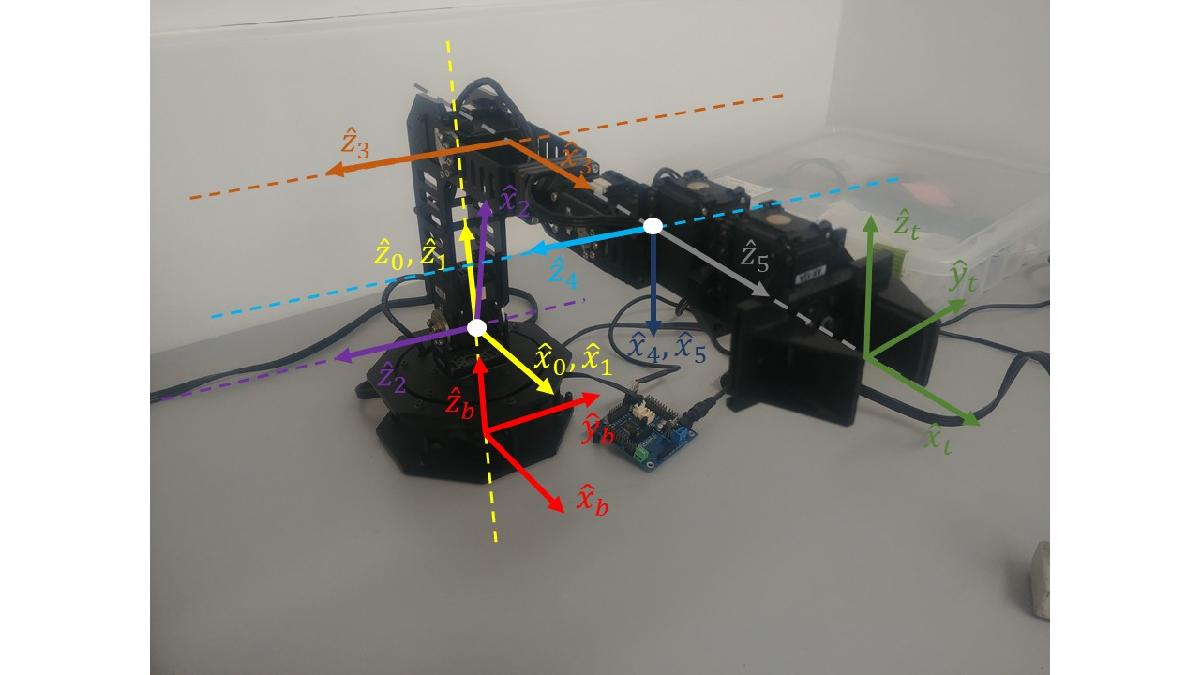

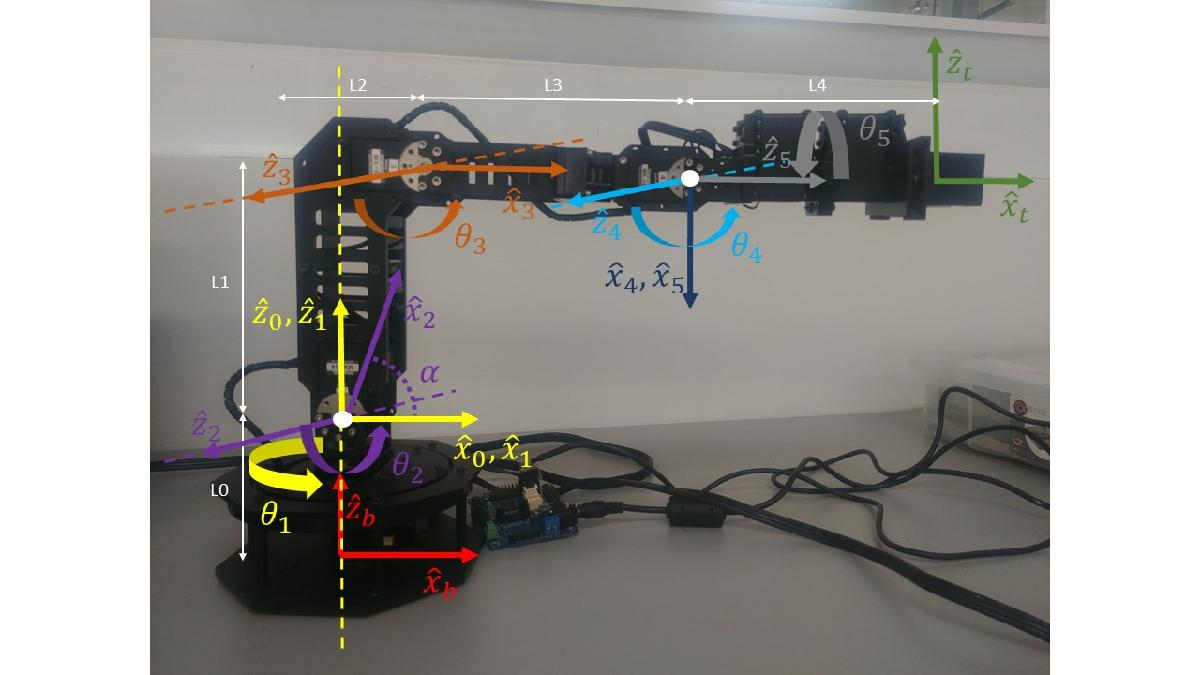

A partir del planteamiento de los ejes coordenados, se obtienen los siguientes parámetros de Denavit y Hartenberg. Se observa que $\alpha =\textrm{atan}\left(\frac{L_1 }{L_2 }\right)$ y $D=\sqrt{L_1^2 +L_2^2 }$

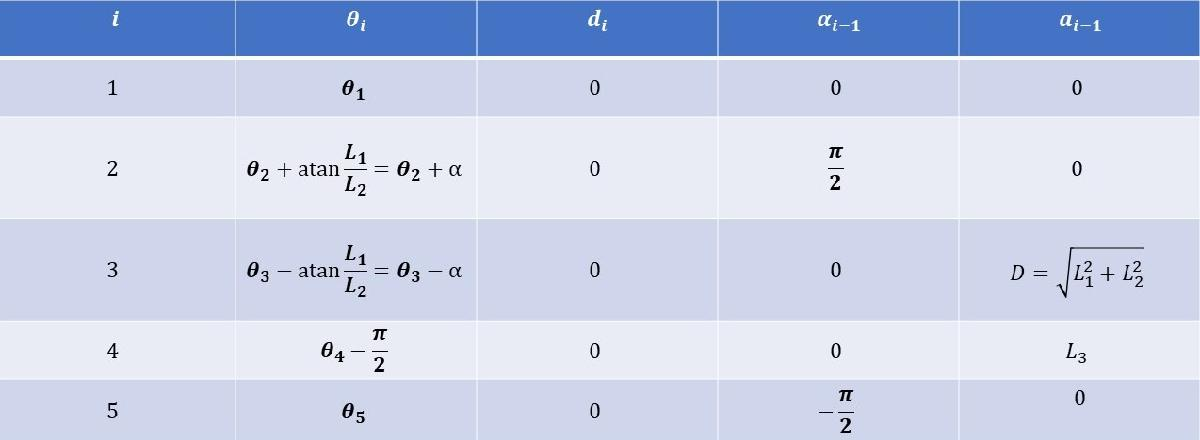

## Cinemática Directa

A partir de estos valores, con ayuda de la función MaTranH para obtener las matrices de transformación homogénea entre articulaciones, se describe la cinemática directa del manipulador.

clear;
%Definición de variables simbólicas
syms q1 q2 q3 q4 q5 L0  L1 L2 L3 L4 pi a D

Tb0 = [eye(3) [0;0;L0]; 0 0 0 1]; %Matriz TH base --> origen
T01 = MaTranH(q1,0,0,0); %Matriz TH origen --> 1
T12 = MaTranH(q2+a, 0, pi/2,0); %Matriz TH 1 --> 2
T23 = MaTranH(q3-a,0,0,D);%Matriz TH 2 --> 3
T34 = MaTranH(q4-pi/2,0,0,L3); %Matriz TH 3 --> 4
T45 = MaTranH(q5,0,-pi/2,0); %Matriz TH 4 --> 5
T5t = [RotY(-pi/2) [0;0; L4]; 0 0 0 1]; %Matriz TH 5 --> tool
T15 = simplify(T12*T23*T34)*T45; %Matriz TH 1 --> 5
T05 = simplify(T01*T15); %Matriz TH 0 --> 5
T1t = simplify(T15*T5t); %Matriz TH 1 --> tool
Ttotal = simplify(Tb0*T01)*T1t %Matriz TH base --> tool

$$Ttotal = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(q_{1}\right) & -\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)-\sigma_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{5}\right)-\sigma_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{5}\right) & \cos\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{5}\right)-\sigma_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{5}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)-\sigma_{1}\,\cos\left(q_{5}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3}\,\sin\left(q_{5}\right) & \sigma_{3}\,\cos\left(q_{5}\right) & L_{0}+\text{D}\,\sin\left(a+q_{2}\right)+L_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{4}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\text{D}\,\cos\left(a+q_{2}\right)+L_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{4}\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

## Cinemática Inversa

Se busca resolver la cinemática inversa del manipulador a partir del sistema coordenado 1. Esto permitirá simplificar la matemática. Cuando se analiza el manipulador desde el sistema 1, se observa que este sólo puede tener movimiento en dos dimensiones, la $\hat{x}$ y $\hat{z}$ del sistema 1. En realidad, cuando el sistema se describe desde la base, el punto ${}^1P_i = [x\ 0 \ z]^T \equiv R_z(\theta_1){}^0P_i + [0 \ 0 \ L0]^T$. Es decir, ${}^1P_x = \sqrt{{}^0P_x^2 + {}^0P_y^2}$, $\theta_1 = atan2({}^0P_y,{}^0P_x)$ y ${}^1P_z={}^0P_z-L_0
$

### Punto deseado con $\theta_4$ conocido

Utilizando la matriz de transformación homogénea de 1 a tool, se obtienen los valores articulares para posicionar el origen de tool en el punto deseado ${\left\lbrack P_x \;P_y \;P_z \right\rbrack }^T$

Se propone entonces $T_d =\left\lbrack \begin{array}{cccc}
r_{11}  & r_{12}  & r_{13}  & P_x \\
r_{21}  & r_{22}  & r_{33}  & P_y \\
r_{31}  & r_{32}  & r_{33}  & P_z \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \equiv$${}^1_tT$

syms r11 r12 r13 r21 r22 r23 r31 r32 r33 Px Py Pz
Td = [r11 r12 r13 Px; r21 r22 r23 Py; r31 r32 r33 Pz; 0 0 0 1]; 
disp([Td(1:3, 4) T1t(1:3, 4)])

$$\left(\begin{array}{cc} \mathrm{Px} & \text{D}\,\cos\left(a+q_{2}\right)+L_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \mathrm{Py} & 0\\ \mathrm{Pz} & \text{D}\,\sin\left(a+q_{2}\right)+L_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right) \end{array}\right)$$

#### Valor articular $\theta_3$

Se intenta $P_x^2 +P_z^2$

collect(expand(simplify(T1t(1,4)^2+T1t(3,4)^2)), [sin(q3), cos(q3)])

$$ans = \left(2\,\text{D}\,L_{3}\,\sin\left(a\right)-2\,\text{D}\,L_{4}\,\cos\left(a\right)\,\sin\left(q_{4}\right)+2\,\text{D}\,L_{4}\,\sin\left(a\right)\,\cos\left(q_{4}\right)\right)\,\sin\left(q_{3}\right)+\left(2\,\text{D}\,L_{3}\,\cos\left(a\right)+2\,\text{D}\,L_{4}\,\cos\left(a\right)\,\cos\left(q_{4}\right)+2\,\text{D}\,L_{4}\,\sin\left(a\right)\,\sin\left(q_{4}\right)\right)\,\cos\left(q_{3}\right)+{\text{D}}^{2}+{L_{3}}^{2}+2\,\cos\left(q_{4}\right)\,L_{3}\,L_{4}+{L_{4}}^{2}$$


$$\begin{array}{l}
a=L_3 c_{\alpha } +L_4 c_{\alpha } c_4 +L_4 s_{\alpha } s_4 \\
b=L_3 s_{\alpha } -L_4 c_{\alpha } s_4 +L_4 s_{\alpha } c_4 \\
c=\frac{P_x^2 +P_z^2 -D^2 -L_3^2 -L_4^2 -2L_3 L_4 c_4 }{2D}\\
\theta_3 =2\textrm{atan2}\left(b\pm \sqrt{a^2 +b^2 -c^2 },a+c\right)\\
\theta_3 =\textrm{atan2}\left(s_3 ,c_3 \right)\\
\textrm{si}\;a^2 +b^2 -c^2 \ge 0
\end{array}$$


#### Valor articular $\theta_2$

disp([str2sym("Px")  collect(expand(T1t(1,4)),[sin(q2), cos(q2)]); 
str2sym("Pz") collect(expand(T1t(3,4)),[sin(q2), cos(q2)])])

$$\begin{array}{l} \left(\begin{array}{cc} \mathrm{Px} & \left(-\text{D}\,\sin\left(a\right)-L_{3}\,\sin\left(q_{3}\right)-\sigma_{3}-\sigma_{2}\right)\,\sin\left(q_{2}\right)+\sigma_{1}\,\cos\left(q_{2}\right)\\ \mathrm{Pz} & \sigma_{1}\,\sin\left(q_{2}\right)+\left(\text{D}\,\sin\left(a\right)+L_{3}\,\sin\left(q_{3}\right)+\sigma_{3}+\sigma_{2}\right)\,\cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{D}\,\cos\left(a\right)+L_{3}\,\cos\left(q_{3}\right)+L_{4}\,\cos\left(q_{3}\right)\,\cos\left(q_{4}\right)-L_{4}\,\sin\left(q_{3}\right)\,\sin\left(q_{4}\right)\\ \sigma_{2}=L_{4}\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=L_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right) \end{array}$$


$$\begin{array}{l}
a=\textrm{Dcos}\left(\alpha \right)+L_3 \cos \left(\theta_3 \right)+L_4 c_3 c_4 -L_4 s_3 s_4 \\
b=\textrm{Dsin}\left(\alpha \right)+L_3 \sin \left(\theta_3 \right)+L_4 s_3 c_4 +L_4 c_3 s_4 \\
\theta_2 =\textrm{atan2}\left({a*P}_z -{b*P}_x ,a*P_x +b*P_z \right)
\end{array}$$


Esto resulta en la función de la cinemática inversa getIK_Q4.

### Punto deseado con $\gamma$ conocido

Utilizando la matriz de transformación homogénea de 1 a 5, se obtienen los valores articulares para posicionar el origen de 5 en el punto deseado ${\left\lbrack P_x \;P_y \;P_z \right\rbrack }^T$

Se propone entonces $T_d =\left\lbrack \begin{array}{cccc}
r_{11}  & r_{12}  & r_{13}  & P_x \\
r_{21}  & r_{22}  & r_{33}  & P_y \\
r_{31}  & r_{32}  & r_{33}  & P_z \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \equiv$${}^1_5T$

disp([Td(1:3, 4) T15(1:3, 4)])

$$\left(\begin{array}{cc} \mathrm{Px} & \text{D}\,\cos\left(a+q_{2}\right)+L_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \mathrm{Py} & 0\\ \mathrm{Pz} & \text{D}\,\sin\left(a+q_{2}\right)+L_{3}\,\sin\left(q_{2}+q_{3}\right) \end{array}\right)$$

#### Valor articular $\theta_3$

Se intenta $P_x^2 +P_z^2$

disp([Td(1,4)^2+Td(3,4)^2 simplify(T15(1,4)^2+T15(3,4)^2)])

$$\left(\begin{array}{cc} {\mathrm{Px}}^{2}+{\mathrm{Pz}}^{2} & {\text{D}}^{2}+2\,\cos\left(a-q_{3}\right)\,\text{D}\,L_{3}+{L_{3}}^{2} \end{array}\right)$$


$$\theta_3 =\alpha \mp \textrm{acos}\left(\frac{P_x^2 +P_z^2 -D^2 -L_3^2 }{2{\textrm{DL}}_3 }\right)$$


#### Valor articular $\theta_2$

disp([str2sym("Px")  collect(expand(T15(1,4)),[sin(q2), cos(q2)]); 
str2sym("Pz") collect(expand(T15(3,4)),[sin(q2), cos(q2)])])

$$\left(\begin{array}{cc} \mathrm{Px} & \left(-\text{D}\,\sin\left(a\right)-L_{3}\,\sin\left(q_{3}\right)\right)\,\sin\left(q_{2}\right)+\left(\text{D}\,\cos\left(a\right)+L_{3}\,\cos\left(q_{3}\right)\right)\,\cos\left(q_{2}\right)\\ \mathrm{Pz} & \left(\text{D}\,\cos\left(a\right)+L_{3}\,\cos\left(q_{3}\right)\right)\,\sin\left(q_{2}\right)+\left(\text{D}\,\sin\left(a\right)+L_{3}\,\sin\left(q_{3}\right)\right)\,\cos\left(q_{2}\right) \end{array}\right)$$


$$\begin{array}{l}
a=\textrm{Dcos}\left(\alpha \right)+L_3 \cos \left(\theta_3 \right)\\
b=\textrm{Dsin}\left(\alpha \right)+L_3 \sin \left(\theta_3 \right)\\
\theta_2 =\textrm{atan2}\left({a*P}_z -{b*P}_x ,a*P_x +b*P_z \right)
\end{array}$$


En este caso, se desea una rotación $R_y \left(\gamma \right)$respecto al sistema 1 para que el gripper apunte siempre hacia el mismo lugar.

La rotación ${}^1_tR = R_x \left(\frac{\pi }{2}\right)R_z \left(\theta_2 +\alpha \right)R_z \left(\theta_3 -\alpha \;\right)R_z \left(\theta_4 -\frac{\pi }{2}\right)R_x \left(-\frac{\pi }{2}\right)R_y \left(-\frac{\pi }{2}\right)R_x \left(\theta_5 \right)$

que se reduce a ${}^1_tR_d = R_y(-\theta_2-\theta_3-\theta_4)R_x(\theta_5) =  R_y(\gamma)R_x(\theta_5)$, donde $\gamma =-\theta_2 -\theta_3 -\theta_4$

Se tiene ahora la matriz de transformación $T_f$ que va del sistema 1 a la herramienta.


$${}^1_5T_d\;\: {}^5_{tool} T = T_f \;\;\therefore {}^1_5T_d = T_f \;\; {}^5_{tool} T^{-1}$$


syms Rd11 Rd12 Rd13 Rd21 Rd22 Rd23 Rd31 Rd32 Rd33 Pxf Pyf Pzf gamma
Rd = [Rd11 Rd12 Rd13; Rd21 Rd22 Rd23; Rd31 Rd32 Rd33];
Tf = [Rd [Pxf; 0; Pzf]; 0 0 0 1]

$$Tf = \left(\begin{array}{cccc} {\mathrm{Rd}}_{11} & {\mathrm{Rd}}_{12} & {\mathrm{Rd}}_{13} & \mathrm{Pxf}\\ {\mathrm{Rd}}_{21} & {\mathrm{Rd}}_{22} & {\mathrm{Rd}}_{23} & 0\\ {\mathrm{Rd}}_{31} & {\mathrm{Rd}}_{32} & {\mathrm{Rd}}_{33} & \mathrm{Pzf}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tff = [simplify(RotY(gamma)*RotX(q5)) [Pxf; 0; Pzf]; 0 0 0 1]

$$Tff = \left(\begin{array}{cccc} \cos\left(\gamma \right) & \sin\left(\gamma \right)\,\sin\left(q_{5}\right) & \cos\left(q_{5}\right)\,\sin\left(\gamma \right) & \mathrm{Pxf}\\ 0 & \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0\\ -\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(q_{5}\right) & \cos\left(\gamma \right)\,\cos\left(q_{5}\right) & \mathrm{Pzf}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Td = Tf/T5t

$$Td = \left(\begin{array}{cccc} -{\mathrm{Rd}}_{13} & {\mathrm{Rd}}_{12} & {\mathrm{Rd}}_{11} & \mathrm{Pxf}-L_{4}\,{\mathrm{Rd}}_{11}\\ -{\mathrm{Rd}}_{23} & {\mathrm{Rd}}_{22} & {\mathrm{Rd}}_{21} & -L_{4}\,{\mathrm{Rd}}_{21}\\ -{\mathrm{Rd}}_{33} & {\mathrm{Rd}}_{32} & {\mathrm{Rd}}_{31} & \mathrm{Pzf}-L_{4}\,{\mathrm{Rd}}_{31}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tdd = Tff/T5t

$$Tdd = \left(\begin{array}{cccc} -\cos\left(q_{5}\right)\,\sin\left(\gamma \right) & \sin\left(\gamma \right)\,\sin\left(q_{5}\right) & \cos\left(\gamma \right) & \mathrm{Pxf}-L_{4}\,\cos\left(\gamma \right)\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ -\cos\left(\gamma \right)\,\cos\left(q_{5}\right) & \cos\left(\gamma \right)\,\sin\left(q_{5}\right) & -\sin\left(\gamma \right) & \mathrm{Pzf}+L_{4}\,\sin\left(\gamma \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

disp([Px Tdd(1,4); Pz Tdd(3,4)])

$$\left(\begin{array}{cc} \mathrm{Px} & \mathrm{Pxf}-L_{4}\,\cos\left(\gamma \right)\\ \mathrm{Pz} & \mathrm{Pzf}+L_{4}\,\sin\left(\gamma \right) \end{array}\right)$$

Dado que se conoce $\gamma$, se obtiene que


$$\theta_4 =-\gamma -\theta_2 -\theta_3$$


De ahí se crea la función getIK_Gamma.

### Punto deseado con rotación deseada conocida

Retomando el resultado anterior, se sabe entonces que

$\cos \left(\gamma \right)={\textrm{Rd}}_{11}$y $\sin \left(\gamma \right)=-{\textrm{Rd}}_{31}$

Por lo tanto, $\gamma =\textrm{atan2}\left(-{\textrm{Rd}}_{31} ,{\textrm{Rd}}_{11} \right)$ y se puede utilizar el mismo procedimiento que se usa cuando se conoce el ángulo $\gamma$.

En este caso, lo que se agrega es el cálculo del quinto valor articular, pues

$R_d =R_y \left(\gamma \right)R_x \left(\theta_5 \right)$, por lo que $R_x \left(\theta_5 \right)=R_y {\left(\gamma \right)}^{-1} R_d =\textrm{Rx5}$.


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c_5  & -s_5 \\
0 & s_5  & c_5 
\end{array}\right\rbrack =\textrm{Rx5}$$



$$\theta_5 =\textrm{atan2}\left({\textrm{Rx5}}_{32} ,{\textrm{Rx5}}_{22} \right)$$


De ahí se crea la función getIK_Rd

### Punto deseado con rotación deseada conocida desde la base

En el caso de que la rotación conocida sea desde la base y no desde el sistema 1, se debe hacer una transformacion, donde


$${}^{base}_tR_d = {}^{base}_1R \ {}^1_tR_d \\ \therefore  {}^{base}_1R^{-1} \ {}^{base}_tR_d = \ {}^1_tR_d$$


Resulta ser que ${}^{base}_1R = R_z(\theta_1)$

Por lo tanto, ${}^1_tR_d = R_z(\theta_1)^{-1} \ {}^{base}_tR_d $

De ahí se crea la función getIK_RdBase

### Sobre las funciones de cinemática inversa

Existen casos en los que no se puede solucionar la cinemática inversa debido a que el punto o la rotación deseada no es alcanzable de ninguna forma. Es decir, que esta fuera del espacio de trabajo del manipulador. Pero hay también otra condición en la que no se puede llegar al punto deseado, y es por la geometría del brazo. Cada eslabón tiene un rango de movimiento delimitado por las características del motor y por el brazo en sí mismo. En el caso de los motores MX-28 y MX-64, el ángulo no es una limitante, pues tienen 360° de acción. Sin embargo, los motores AX-12a tienen 300° de acción, desde -150° hasta 150°. Los límites de la geometría son los siguientes:

- En el motor 1 no hay límite pues puede girar en los 360° sin chocar consigo mismo y el motor llega a esos ángulos

- En el motor 2 el límite de giro es de $\left\lbrack -\frac{\pi }{2},\frac{\pi }{2}\right\rbrack$, más allá de este límite choca con la base del brazo

- En el motor 3 el límite de giro es de $\left\lbrack -\frac{\pi }{2},\frac{5\pi }{6}\right\rbrack$, más allá de este límite choca con la sección del brazo $L_1$

- En el motor 4 el límite de giro es de $\left\lbrack -\frac{\pi }{2},\frac{11\pi }{18}\right\rbrack$, más allá de este límite choca con el tercer motor

- En los motores 5 y 6 el rango de giro es $\left\lbrack -\frac{5\pi }{6},\frac{5\pi }{6}\right\rbrack$, por lo que estos valores son los limites alcanzables por el brazo.

## Simulación con Peter Corke

Aquí se muestra el robot graficado usando la librería de Peter Corke *Robotics Toolbox*. Se puede descargar en: [https://petercorke.com/toolboxes/robotics-toolbox/](https://petercorke.com/toolboxes/robotics-toolbox/)

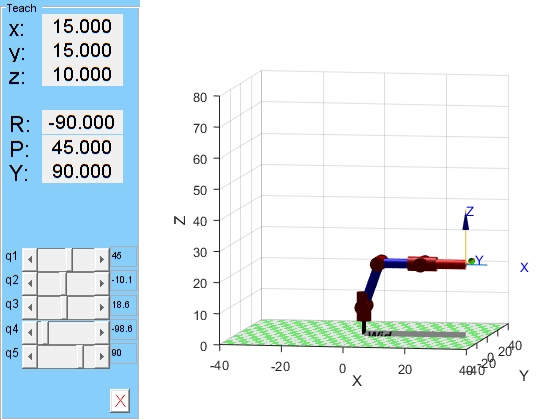

Error using matlab.graphics.primitive.Group/set
Invalid or deleted object.

Error in SerialLink/animate (line 150)
                set(handle, 'UserData', h);

Error in RTBPlot.teach_callback (

clear all;
L0 = 9; L1 = 14; L2 = 5; L3 = 14; L4 = 14;
a = atan(L1/L2); D = sqrt(L1^2+L2^2); 
L(1) = Link([0 0 0 0 0 0], 'modified');
L(2) = Link([0 0 0 pi/2 0 a], 'modified');
L(3) = Link([0 0 D 0 0 -a], 'modified');
L(4) = Link([0 0 L3 0 0 -pi/2], 'modified');
L(5) = Link([0 0 0 -pi/2 0 0], 'modified');
qlimit = pi*[-2 2; -0.5 0.5; -0.5 5/6; -11/18 0.5; -5/6 5/6];
q0 = [0 0 0 0 0];
WidowX = SerialLink(L, 'name', 'Widow X II', 'qlim', qlimit);
WidowX.tool = [RotY(-pi/2) [0;0;L4]; 0 0 0 1];
WidowX.base = [eye(3) [0;0;L0]; 0 0 0 1];
WidowX.plot(q0, 'workspace',2*[-40 40 -40 40 0 40]);
WidowX.plot(q0, 'floorlevel',0);    
WidowX.teach(q0); %Dibuja el robot en la posición de home

hold on;
trplot(eye(4), 'frame','0','color','k');
hold off;


### IK con Q4

q0 = getIK_Q4(10,0,30,-pi/4)

q0 =          0    1.3348   -0.4216   -0.7854         0


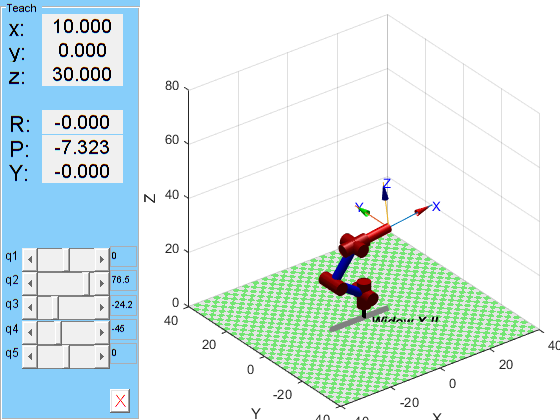

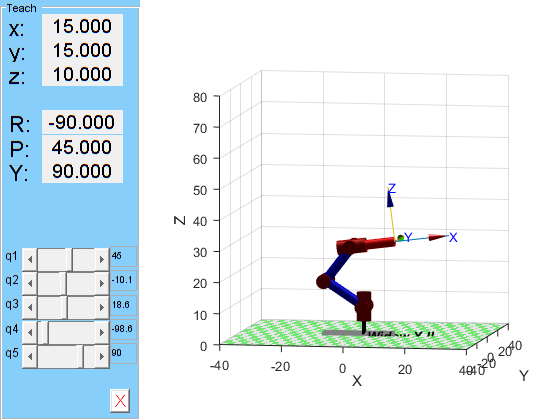

figure()
WidowX.plot(q0,'workspace',[-40 40 -40 40 0 80]);
WidowX.teach(q0);

### IK con Gamma

q0 = getIK_Gamma(15,15,40,-pi/2)

q0 =     0.7854   -0.8846    1.9141    0.5413         0


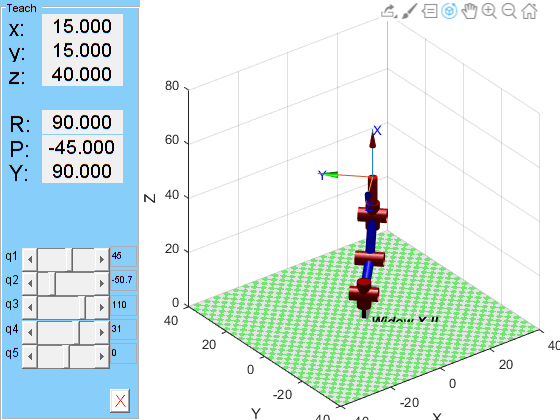

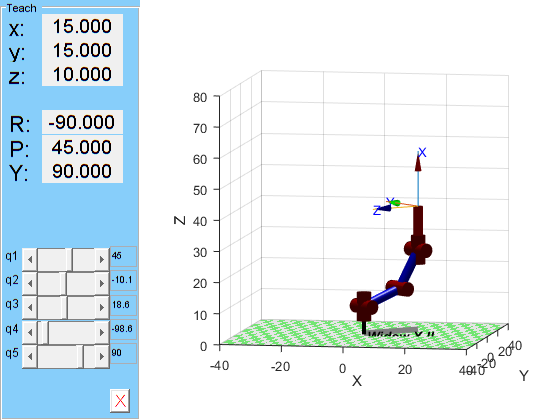

figure()
WidowX.plot(q0,'workspace',[-40 40 -40 40 0 80]);
WidowX.teach(q0);

### IK con Rd

q0 = getIK_Rd(15,-10,35,RotX(pi/2))

q0 =    -0.5880   -0.2213    2.0762   -1.8548    1.5708


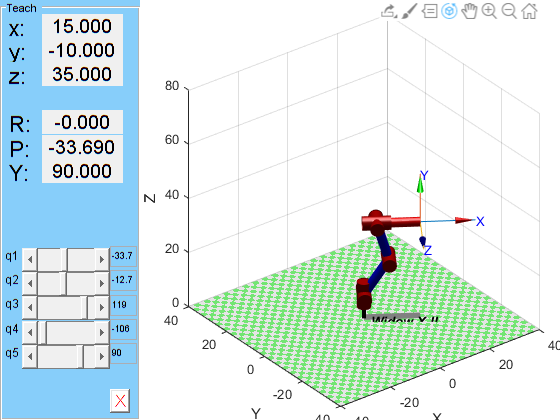

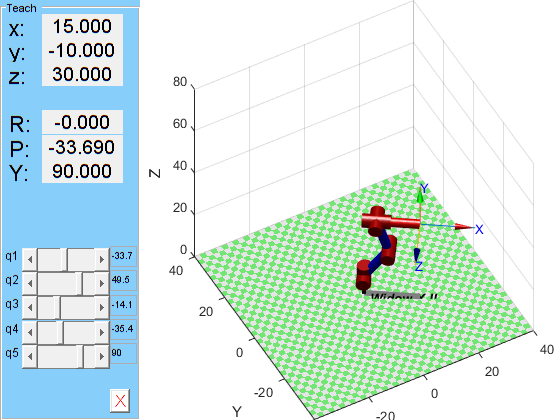

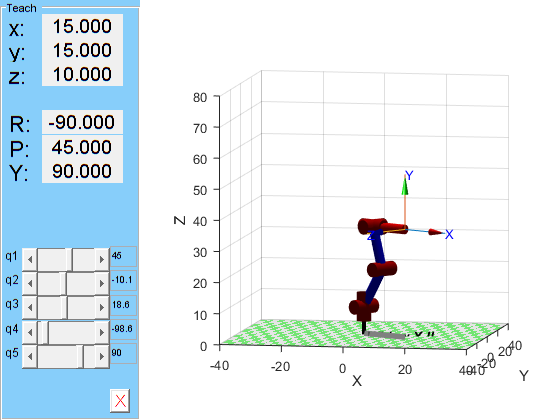

figure()
WidowX.plot(q0,'workspace',[-40 40 -40 40 0 80]);
WidowX.teach(q0);

### IK con Rd desde Base

q0 = getIK_RdBase(13,10,40,RotY(-pi/2))

q0 =     0.6557   -1.0160    2.4530    0.1338   -0.6557


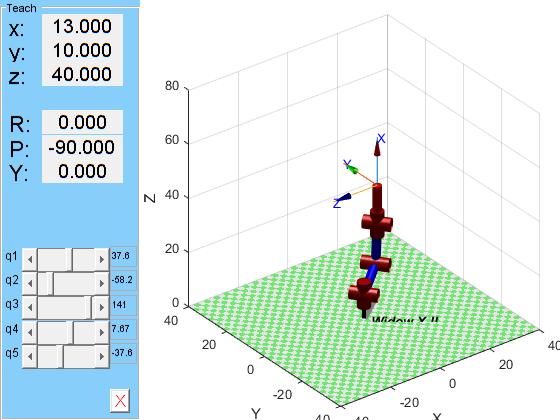

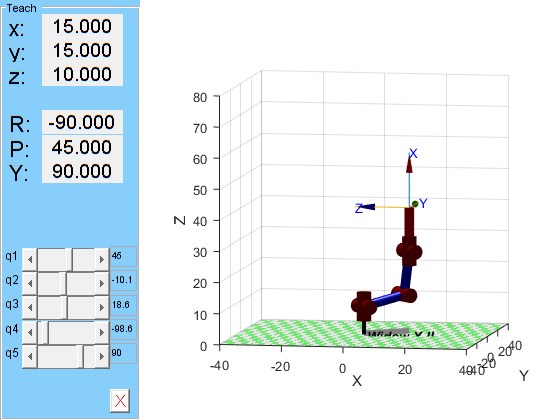

figure()
WidowX.plot(q0,'workspace',[-40 40 -40 40 0 80]);
WidowX.teach(q0);

## Anexos

### Función *MaTranH*

function T = MaTranH(qi,di,alfai_1,ai_1)
%Esta función regresa la matriz de transformación homogénea
%Utilizando los parámetros de Denavit y Hartenberg
%Usa los parámetros MaTranH(qi,di,alfai_1,ai_1) (en radianes los ángulos)
%La matriz se calcula así:
%T = [cos(qi) -sin(qi) 0 ai_1;
%  sin(qi)*cos(alfai_1) cos(qi)*cos(alfai_1) -sin(alfai_1) -di*sin(alfai_1);
%  sin(qi)*sin(alfai_1) cos(qi)*sin(alfai_1) cos(alfai_1) di*cos(alfai_1);
%  0 0 0 1];

T = [cos(qi) -sin(qi) 0 ai_1;
  sin(qi)*cos(alfai_1) cos(qi)*cos(alfai_1) -sin(alfai_1) -di*sin(alfai_1);
  sin(qi)*sin(alfai_1) cos(qi)*sin(alfai_1) cos(alfai_1) di*cos(alfai_1);
  0 0 0 1
];

if ~isnumeric([qi di alfai_1 ai_1])
    T = simplify(T);
end
end

#### Función *getIK_Q4*

function q = getIK_Q4(Px,Py,Pz,theta4)
%Esta función calcula la cinemática inversa del manipulador, dado el punto
%desde el origen, cuando se conoce el valor articular q4 y se desea dejar
%fijo dicho valor. Los puntos se reciben en centímetros y el ángulo q4 en
%radianes.
    clear L0 L1 L2 L3 L4 q1 q2 q3 q4 q5 pi gamma beta
    limPi_2 = 181*pi/360; %limite de la geometría del robot para los valores cercanos a pi/2
    L0 = 9; L1 = 14; L2 = 5; L3 = 14; L4 = 14; %distancias en cm del manipulador
    alpha = atan(L1/L2); D = sqrt(L1^2+L2^2);  %constantes
    
    q1 = atan2(Py,Px);
    
    X = sqrt(Px^2+Py^2);
    Z = Pz - L0;
    
    sa = sin(alpha); ca = cos(alpha);
    s4 = sin(theta4); c4 = cos(theta4);
    
    a = L3*ca+L4*ca*c4+L4*sa*s4;
    b = L3*sa-L4*ca*s4+L4*sa*c4;
    c = (X^2+Z^2-D^2-L3^2-L4^2-2*L3*L4*c4)/(2*D);
    
    cond = a^2+b^2-c^2;
    if(cond<0)
        disp("No hay solución de la IK");
        return;
    end
      
    q3 = 2*atan2(b - sqrt(cond),a+c);
    q3 = atan2(sin(q3), cos(q3));  
    tryTwice = true;
    if(q3 > 5*pi/6 || q3 < -limPi_2)
        q3 = 2*atan2(b + sqrt(cond),a+c);
        q3 = atan2(sin(q3), cos(q3));
        tryTwice = false;
        if(q3 > 5*pi/6 || q3 < -limPi_2)
            disp('No hay solución dada la geometría del brazo')
            return;
        end
    end
    
    while(true)
        c3 = cos(q3); s3 = sin(q3);
    
        a = D*ca+L3*c3+L4*c3*c4-L4*s3*s4;
        b = D*sa+L3*s3+L4*s3*c4+L4*c3*s4;
        q2 = atan2(a*Z - b*X, a*X + b*Z);
        
        if(abs(q2) > limPi_2)
            if(tryTwice)
                q3 = 2*atan2(b + sqrt(cond),a+c);
                q3 = atan2(sin(q3), cos(q3));
                if(q3 > 5*pi/6 || q3 < -limPi_2)
                    disp('No hay solución dada la geometría del brazo en q3')
                    return;
                end
                tryTwice = false;
                continue
            else
                disp('No hay solución dada la geometría del brazo en q2')
                return
            end
            
        end
        break
    end    
    q = [q1 q2 q3 theta4 0];
end


#### Función *getIK_Gamma*

function q = getIK_Gamma(Px,Py,Pz,gamma)
%Esta función calcula la cinemática inversa del manipulador, dado el punto
%desde el origen, cuando se conoce el ángulo del gripper respecto al eje x del sistema 1 
% Los puntos se reciben en centímetros y el ángulo gamma en radianes.

    clear L0 L1 L2 L3 L4 q1 q2 q3 q4 q5 pi beta alpha D sa ca sg ca X Z c
    limPi_2 = 181*pi/360; %limite de la geometría del robot para los valores cercanos a pi/2
    L0 = 9; L1 = 14; L2 = 5; L3 = 14; L4 = 14; %distancias en cm del manipulador
    alpha = atan(L1/L2); D = sqrt(L1^2+L2^2);  %constantes
    
    X = sqrt(Px^2+Py^2);
    Z = Pz - L0;
    
    sa = sin(alpha); ca = cos(alpha);
    sg = sin(gamma); cg = cos(gamma);
    
    X = X - L4*cg;
    Z = Z + L4*sg;
    
    %Tercer valor articular
    c = (X^2+Z^2-D^2-L3^2)/(2*D*L3);
    if(abs(c)>1)
        disp('No hay solución de la IK')
        return;
    end
    
    q3 = alpha + acos(c);
    q3 = atan2(sin(q3), cos(q3));
    tryTwice = true;
    if(q3 > 5*pi/6 || q3 < -limPi_2)
        q3 = alpha - acos(c);
        q3 = atan2(sin(q3), cos(q3));
        tryTwice = false;
        if(q3 > 5*pi/4 || q3 < -limPi_2)
            disp('No hay solución dada la geometría del brazo')
            return;
        end
    end
    
    while(true)
        c3 = cos(q3); s3 = sin(q3);
    
        a = D*ca+L3*c3;
        b = D*sa+L3*s3;
        q2 = atan2(a*Z - b*X, a*X + b*Z);
            
        if(abs(q2) > limPi_2)
            if(tryTwice)
                q3 = alpha - acos(c);
                q3 = atan2(sin(q3), cos(q3));
                if(q3 > 5*pi/6 || q3 < -limPi_2)
                    disp('No hay solución dada la geometría del brazo en q3')
                    return;
                end
                tryTwice = false;
                continue
            else
                disp('No hay solución dada la geometría del brazo en q2')
                return
            end
        end
        
        q4 = -gamma - q2 - q3;
    
        if(q4 < -11*pi/18 || q4>limPi_2)
            if(tryTwice)
                q3 = alpha - acos(c);
                q3 = atan2(sin(q3), cos(q3));
                if(q3 > 5*pi/6 || q3 < -limPi_2)
                    disp('No hay solución dada la geometría del brazo en q3')
                    return;
                end
                tryTwice = false;
                continue
            else
                disp('No hay solución dada la geometría del brazo en q4')
                return
            end
        end
        
        break
    end
    
    q1 = atan2(Py,Px);
    
    q = [q1 q2 q3 q4 0];
end


### Función *getIK_Rd*

function q = getIK_Rd(Px,Py,Pz,Rd)
%Esta función calcula la cinemática inversa del manipulador, dado el punto
%desde el origen, cuando se conoce la rotación del gripper respecto del 
%sistema 1. Los puntos se reciben en centímetros y el ángulo gamma en radianes.

    [r,c] = size(Rd);
    if(r ~=3 && c~=3)
       disp('La matriz de rotación no es de 3x3');
       return;
    end
    
    clear L0 L1 L2 L3 L4 q1 q2 q3 q4 q5 pi beta gamma
    limPi_2 = 181*pi/360; %limite de la geometría del robot para los valores cercanos a pi/2
    L0 = 9; L1 = 14; L2 = 5; L3 = 14; L4 = 14; %distancias en cm del manipulador
    alpha = atan(L1/L2); D = sqrt(L1^2+L2^2);  %constantes
    
    X = sqrt(Px^2+Py^2);
    Z = Pz - L0;
    
    sa = sin(alpha); ca = cos(alpha);
    sg = -Rd(3,1); cg = Rd(1,1);
    
    
    X = X - L4*cg;
    Z = Z + L4*sg;
    
    %Tercer valor articular
    c = (X^2+Z^2-D^2-L3^2)/(2*D*L3);
    if(abs(c)>1)
        disp('No hay solución de la IK')
        return;
    end
    
    q3 = alpha + acos(c);
    q3 = atan2(sin(q3), cos(q3));
    tryTwice = true;
    if(q3 > 5*pi/6 || q3 < -limPi_2)
        q3 = alpha - acos(c);
        q3 = atan2(sin(q3), cos(q3));
        tryTwice = false;
        if(q3 > 5*pi/4 || q3 < -limPi_2)
            disp('No hay solución dada la geometría del brazo')
            return;
        end
    end
    
    gamma = atan2(sg,cg);
    while(true)
        c3 = cos(q3); s3 = sin(q3);
    
        a = D*ca+L3*c3;
        b = D*sa+L3*s3;
        q2 = atan2(a*Z - b*X, a*X + b*Z);
            
        if(abs(q2) > limPi_2)
            if(tryTwice)
                q3 = alpha - acos(c);
                q3 = atan2(sin(q3), cos(q3));
                if(q3 > 5*pi/6 || q3 < -limPi_2)
                    disp('No hay solución dada la geometría del brazo en q3')
                    return;
                end
                tryTwice = false;
                continue
            else
                disp('No hay solución dada la geometría del brazo en q2')
                return
            end
        end
        
        q4 = -gamma - q2 - q3;
    
        if(q4 < -11*pi/18 || q4>limPi_2)
            if(tryTwice)
                q3 = alpha - acos(c);
                q3 = atan2(sin(q3), cos(q3));
                if(q3 > 5*pi/6 || q3 < -limPi_2)
                    disp('No hay solución dada la geometría del brazo en q3')
                    return;
                end
                tryTwice = false;
                continue
            else
                disp('No hay solución dada la geometría del brazo en q4')
                return
            end
        end
        
        break
    end
    
    q1 = atan2(Py,Px);
    
    Rx5 = RotY(gamma)\Rd;
    
    q5 = atan2(Rx5(3,2), Rx5(2,2));
    
    if(abs(q5)>5*pi/6)
        disp('No hay rotación posible para q5')
        if(q5<0)
            q5 = -5*pi/6;
        else
            q5 = 5*pi/6;
        end
    end
    
    q = [q1 q2 q3 q4 q5];
end

### Función *getIK_RdBase*

function q = getIK_RdBase(Px,Py,Pz,RdBase)
%Esta función calcula la cinemática inversa del manipulador, dado el punto
%desde el origen, cuando se conoce la rotación del gripper respecto del 
%sistema 1. Los puntos se reciben en centímetros y el ángulo gamma en radianes.

    [r,c] = size(RdBase);
    if(r ~=3 && c~=3)
       disp('La matriz de rotación no es de 3x3');
       return;
    end
    
    clear L0 L1 L2 L3 L4 q1 q2 q3 q4 q5 pi beta gamma
    q1 = atan2(Py,Px);
    Rd = RotZ(q1)\RdBase;
    q = getIK_Rd(Px,Py,Pz,Rd);
end


### Rotaciones

function Rx = RotX(q)
    Rx = [1 0 0; 0 cos(q) -sin(q); 0 sin(q) cos(q)];
end

function Ry = RotY(q)
    Ry = [cos(q) 0 sin(q); 0 1 0; -sin(q) 0 cos(q)];
end

function Rz = RotZ(q)
    Rz = [cos(q) -sin(q) 0; sin(q) cos(q) 0; 0 0 1];
end